## Problem 4

clear;close all;clc;

### Part 4(a)

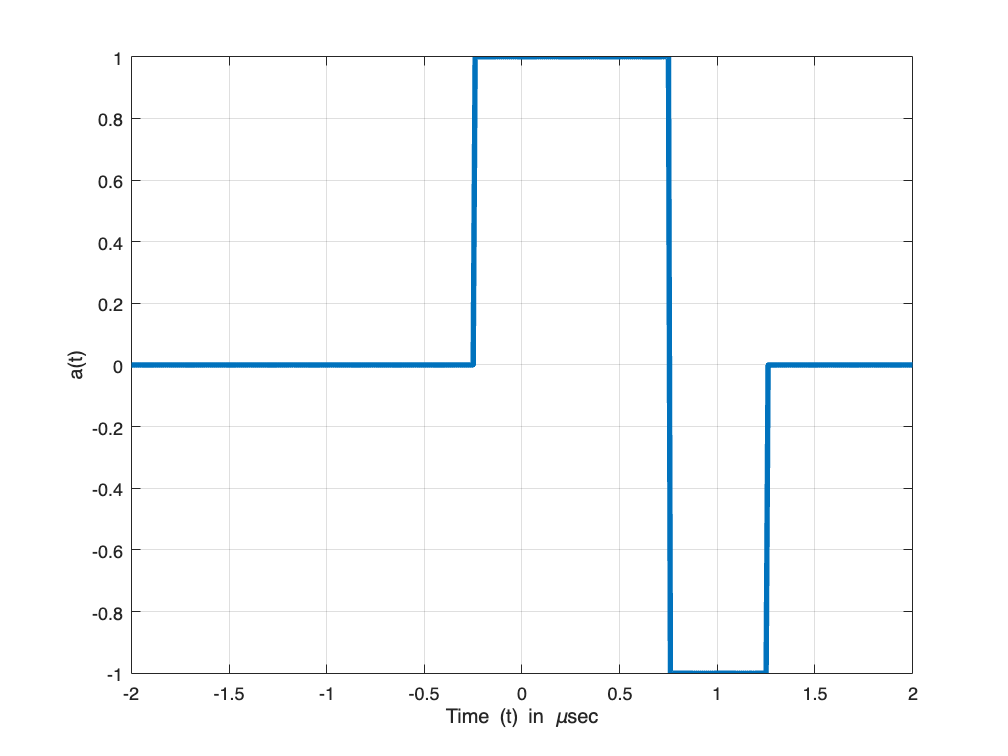

T = 0.5;
t = -4*T:0.01:4*T;
rect =@(t) (t>-0.5) & (t<=0.5);

a =@(t,T) rect(t/T) + rect((t-T)/T) - rect((t-2*T)/T);

plot(t,a(t,T),'LineWidth',3);
grid on; 
xlabel('Time (t) in \musec');
ylabel('a(t)');

### Part 4(b)

Let us solve the Fourier transform here:


$$rect(t) \leftrightarrow sinc(\omega/2\pi)$$



$$rect(t/T) \leftrightarrow T \, sinc(\omega T/2\pi)$$



$$rect((t-T)/T) \leftrightarrow T \, e^{-j\omega T} \, sinc(\omega T/2\pi)$$



$$rect((t-2T)/T) \leftrightarrow T \, e^{-j\,\omega \,2\,T} \, sinc(\omega T/2\pi)$$



$$rect(t/T) + rect((t-T)/T) - rect((t-2T)/T)\leftrightarrow T \, sinc(\omega T/2\pi) + T \, e^{-j\omega T} \, sinc(\omega T/2\pi) - T \, e^{-j\omega 2 T} \, sinc(\omega T/2\pi)$$


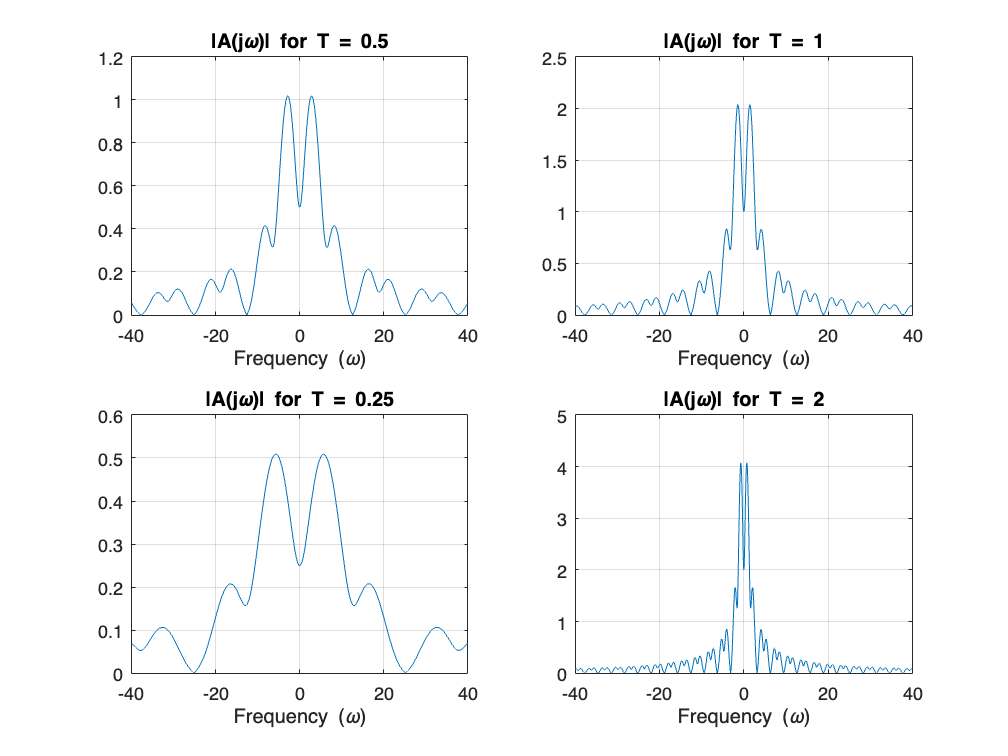

t = -10*T:0.01:10*T;
w = -40:0.01:40;

A =@(w,T) T .* sinc(w*T/(2*pi)) .* ( 1 + exp(-j*w*T) - exp(-j*2*w*T));

figure;
subplot(2,2,1)
plot(w,abs(A(w,T)));grid on;xlabel('Frequency (\omega)');title('|A(j\omega)| for T = 0.5');
subplot(2,2,2)
plot(w,abs(A(w,2*T)));grid on;xlabel('Frequency (\omega)');title('|A(j\omega)| for T = 1');
subplot(2,2,3)
plot(w,abs(A(w,T/2)));grid on;xlabel('Frequency (\omega)');title('|A(j\omega)| for T = 0.25');
subplot(2,2,4)
plot(w,abs(A(w,4*T)));grid on;xlabel('Frequency (\omega)');title('|A(j\omega)| for T = 2');

We can observe that the signal essentially uses infinite bandwidth.

As T is increased, it results in a time expansion in time domain, which has the opposite effect in frequency domain.

As T is decreased, we can observe a corresponding frequency expansion.

### Prob 4(c)

Transmitting sinc pulses, instead of square pulses.

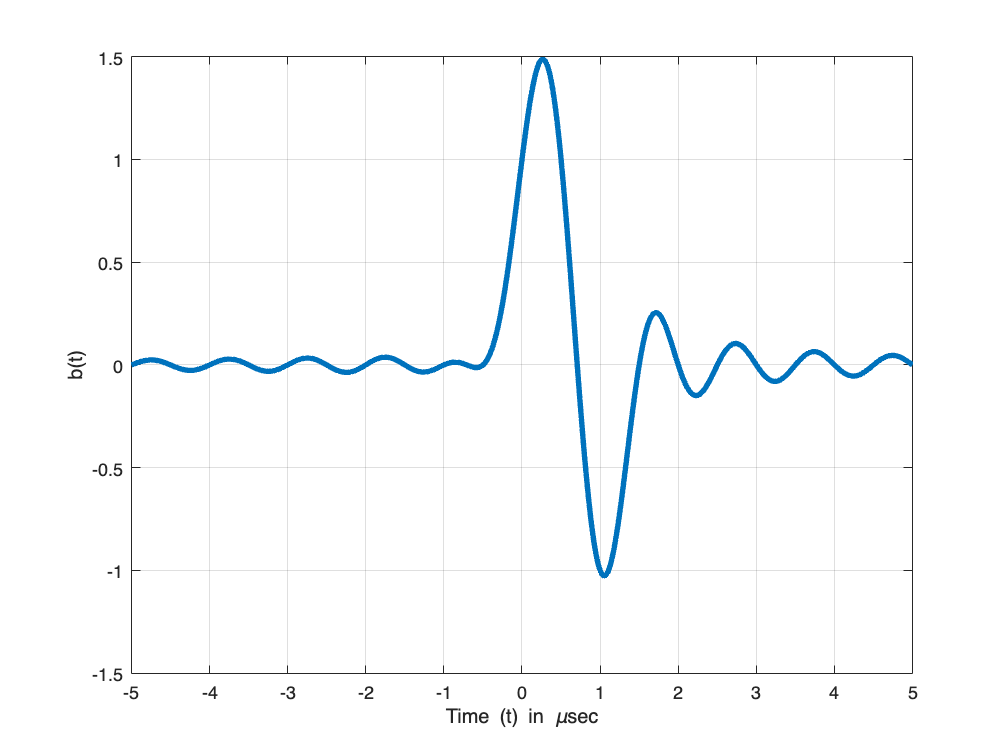

b =@(t,T) sinc(t/T) + sinc((t-T)/T) - sinc((t-2*T)/T);

figure;
plot(t,b(t,T),'LineWidth',3);
grid on; xticks(-10:10);
xlabel('Time (t) in \musec');
ylabel('b(t)');

Here, we have the signal propagated infinitely, since 'sinc' function nevers goes to 0. It can be approximated or truncated for practical purposes, but ideally, it exists throughout all time.

### Prob 4(d)

Now, we will calculate the Fourier transform of b(t). Recalling the duality in rect and sinc functions:


$$sinc(t) \leftrightarrow rect\left(\frac{\omega}{2\pi}\right)$$



$$sinc(t/T) \leftrightarrow T \, rect\left(\frac{\omega T}{2\pi}\right)$$



$$sinc((t-T)/T) \leftrightarrow T \, e^{-j \omega T} \, rect\left(\frac{\omega T}{2\pi}\right)$$



$$sinc((t-2T)/T) \leftrightarrow T \, e^{-j \omega 2T} \, rect\left(\frac{\omega T}{2\pi}\right)$$



$$sinc(t/T) + sinc((t-T)/T) - sinc((t-2T)/T)\leftrightarrow T \, rect\left(\frac{\omega T}{2\pi}\right) + T\, e^{-j \omega T} \, rect\left(\frac{\omega T}{2\pi}\right) - T \, e^{-j \omega 2 T} \, rect\left(\frac{\omega T}{2\pi}\right)$$


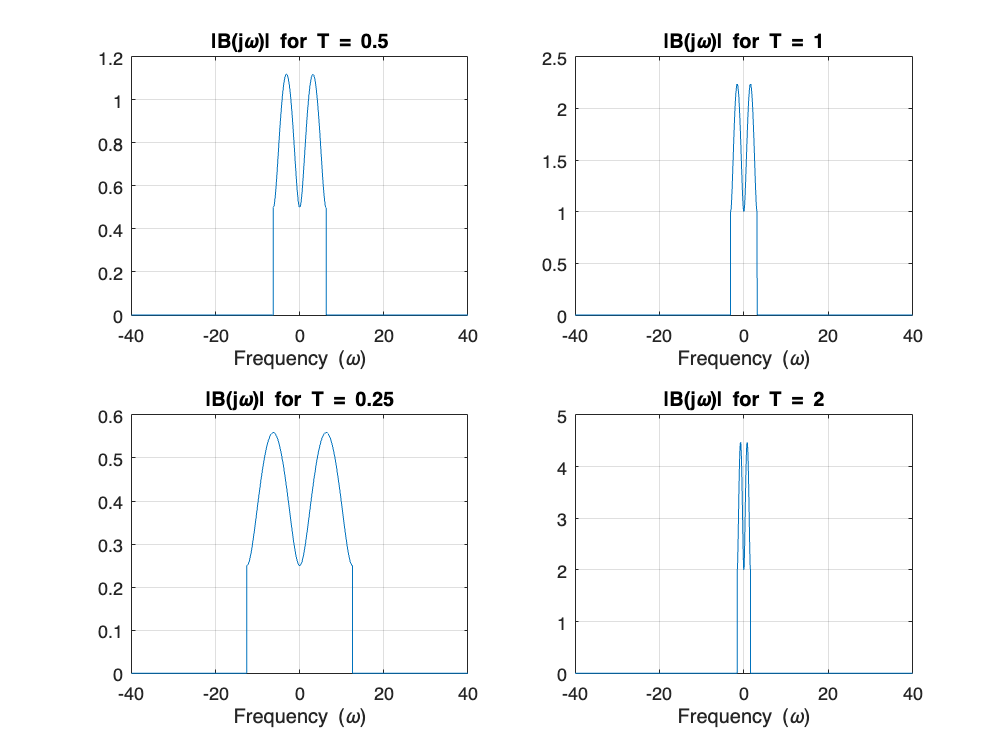

w = -40:0.01:40;
B =@(w,T) T .* rect((w*T)/(2*pi)) .* ( 1 + exp(-j*w*T) - exp(-j*w*2*T));
figure;
subplot(2,2,1)
plot(w,abs(B(w,T)));grid on;xlabel('Frequency (\omega)');title('|B(j\omega)| for T = 0.5');
subplot(2,2,2)
plot(w,abs(B(w,2*T)));grid on;xlabel('Frequency (\omega)');title('|B(j\omega)| for T = 1');
subplot(2,2,3)
plot(w,abs(B(w,T/2)));grid on;xlabel('Frequency (\omega)');title('|B(j\omega)| for T = 0.25');
subplot(2,2,4)
plot(w,abs(B(w,4*T)));grid on;xlabel('Frequency (\omega)');title('|B(j\omega)| for T = 2');

Now, we can see that the frequency response is limited to a small region alone, that is, it uses only little bandwidth compared to infinite bandwidth earlier.

### Prob 4(e)


$$x(t) = b(t) \times cos(2 \pi f_c t)$$



$$x(t) = b(t) \times \left(\frac{e^{2 \pi f_c t} + e^{-2 \pi f_c t}}{2}\right)$$



$$x(t) = \frac{1}{2} \, b(t)\, e^{2 \pi f_c t} + \frac{1}{2} \, b(t)\, e^{-2 \pi f_c t}$$


Now, writing $X(j\omega)$using the frequency shift property:


$$X(j\omega) = \frac{1}{2} B(j(\omega - 2\pi f_c)) + \frac{1}{2} B(j(\omega + 2\pi f_c))$$


Here, $f_c$ is the carrier frequency of 2.4 GHz.

fc = 2.4e9;
w = (2*pi*fc - 40) : 0.01 : (2*pi*fc + 40);
X = (1/2) * B(w - 2*pi*fc,T) + (1/2) * B(w + 2*pi*fc,T);

Since $f_c$ is a large value, showing only one side of frequency:

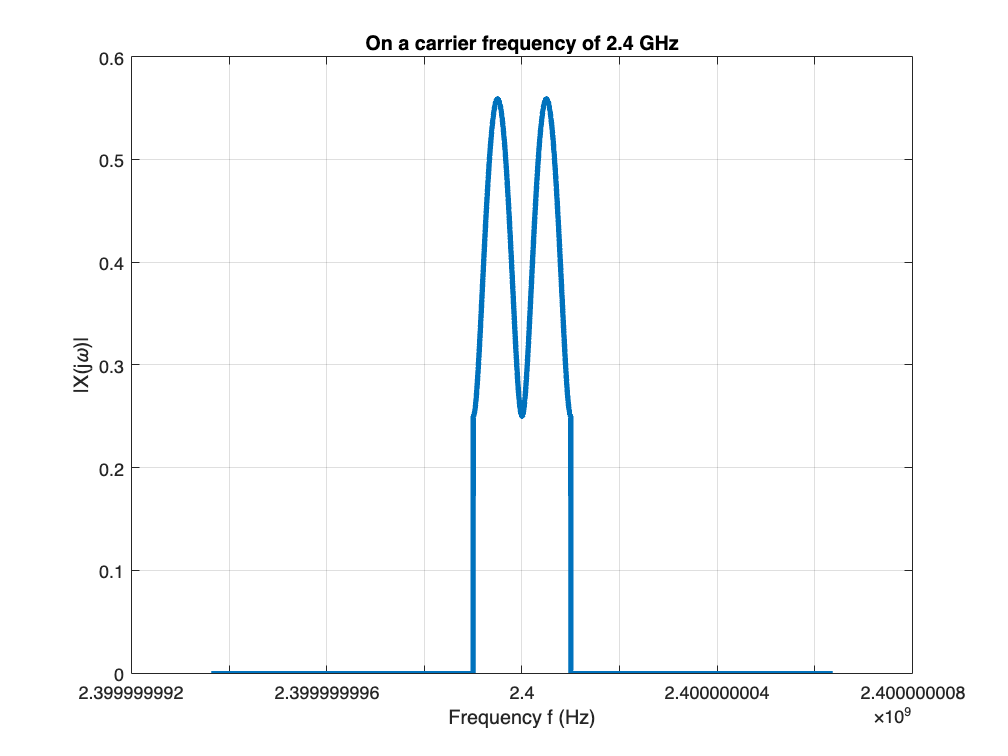

figure;
plot(w/(2*pi),abs(X),'LineWidth',3);
grid on;xlabel('Frequency f (Hz)');
ylabel('|X(j\omega)|');
title('On a carrier frequency of 2.4 GHz')

### Prob 4(f)


$$\hat{x}(t) = x(t) \times rect(\frac{t}{6T})$$



$$\hat{X}(jw) = X(jw) * 6 \text{sinc}(\frac{3\omega}{\pi})$$


Truncation: For this purpose, we will multiply the input signal $x(t)$ with a rectangle function whose edges are at $-3T$ and $3T$.

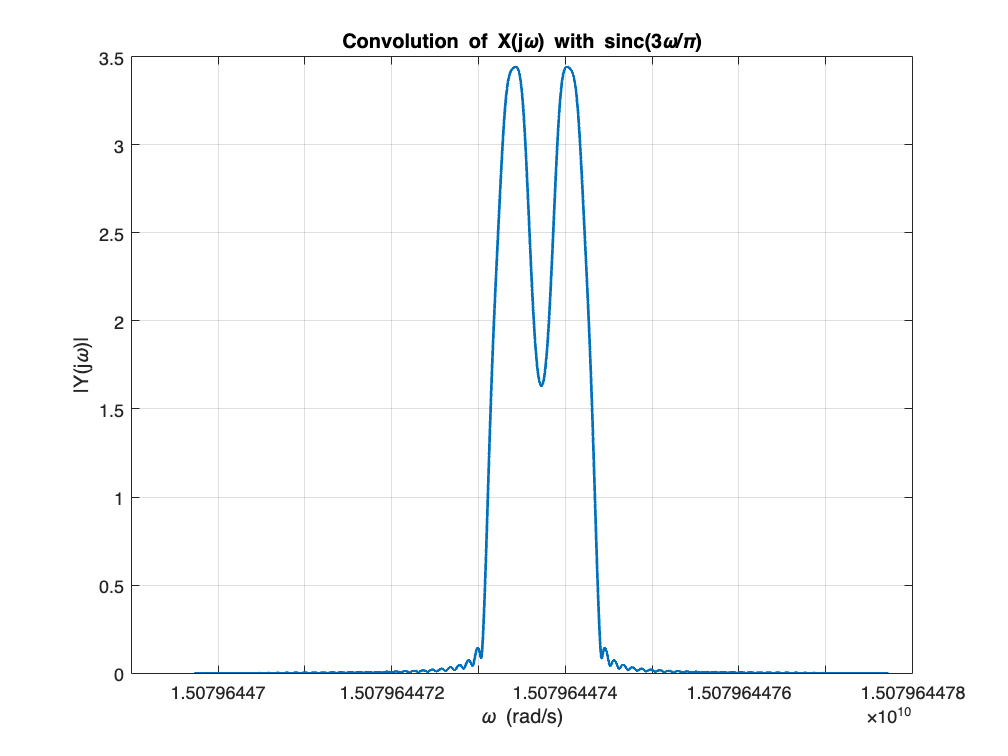

x = (b(t,T) .* cos(2*pi*fc*t));
x_trunc = (b(t,T) .* cos(2*pi*fc*t)) .* rect(t/(6*T));

X = @(w) (1/2) * B(w - 2*pi*fc, T) + (1/2) * B(w + 2*pi*fc, T);
sinc_func = @(w) 6 * sinc(3*w/pi);

dw = w(2) - w(1);

Y = zeros(size(w));

for k = 1:length(w)
    % The integrand is X(w') * sinc(w - w')
    integrand = @(wp) X(wp) .* sinc_func(w(k) - wp);  
    
    % Compute the convolution integral by summing the values
    % We use the trapezoidal rule to approximate the integral
    Y(k) = sum(integrand(w) * dw);  % Approximate the integral as a sum
end

figure;
plot(w, abs(Y), 'LineWidth', 1.5);
xlabel('\omega (rad/s)');
ylabel('|Y(j\omega)|');
title('Convolution of X(j\omega) with sinc(3\omega/\pi)');
grid on;

As we move from non-truncated input to (-3T, 3T) truncation, we see that there is a small difference in the frequency response, but the two peaks are still distinctly evident.